clc, clear
datadir = 'G:\A_arousal_analysis\data';
resultsdir = 'G:\A_arousal_analysis\results';
load(fullfile(resultsdir, 'step_01_pred_study1_perm.mat'),  "rating", "wb_pred_study1", "subject")
load(fullfile(datadir, 'fig_cols.mat'))
fontname = 'Helvetica';

## Calculate correlations for color assignment

uID = unique(subject);
nsub = length(uID);

% PAES predictions: negative affective experience coded as 0
pred_rating = wb_pred_study1(:, 1);
true_rating = rating(:, 1);
subj_plot = subject;
PAES_overall_corrs = zeros(nsub, 1);
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    PAES_overall_corrs(i) = corr(true_rating(subj_idx), pred_rating(subj_idx));
end

% PAES predictions: exclude negative affective experience
video_idx = rating(:, 1) ~= 0;
pred_rating = wb_pred_study1(video_idx, 1);
true_rating = rating(video_idx, 1);
subj_plot = subject(video_idx);
PAES_pos_corrs = zeros(nsub, 1);

for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    PAES_pos_corrs(i) = corr(true_rating(subj_idx), pred_rating(subj_idx));
end

% NAES predictions: positive affective experience coded as 0
pred_rating = wb_pred_study1(:, 2);
true_rating = rating(:, 2);
subj_plot = subject;
NAES_overall_corrs = zeros(nsub, 1);
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    NAES_overall_corrs(i) = corr(true_rating(subj_idx), pred_rating(subj_idx));
end

% NAES predictions: exclude positive affective experience
video_idx = rating(:, 2) ~= 0;
pred_rating = wb_pred_study1(video_idx, 2);
true_rating = rating(video_idx, 2);
subj_plot = subject(video_idx);
NAES_neg_corrs = zeros(nsub, 1);
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    NAES_neg_corrs(i) = corr(true_rating(subj_idx), pred_rating(subj_idx));
end

## Assign colors using a fixed correlation range of [-1, 1]

r_values = [PAES_overall_corrs;PAES_pos_corrs; NAES_overall_corrs; NAES_neg_corrs];
n_colors = size(col_with_white, 1);
% r = -1 maps to col_with_white(1, :)
% r =  1 maps to col_with_white(end, :)
color_idx = round((r_values + 1) ./ 2 .* (n_colors - 1)) + 1;
cols = col_with_white(color_idx, :);

## Figure 1: PAES predictions, negative affective experience coded as 0

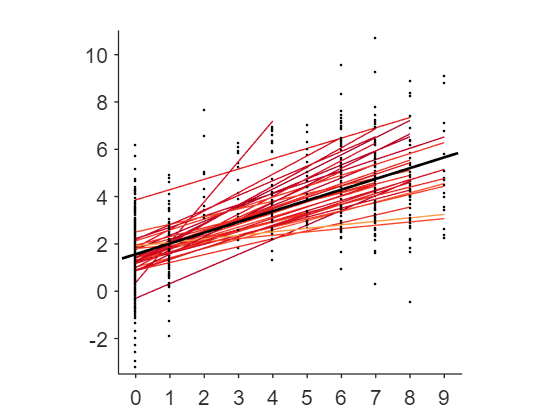

pred_rating = wb_pred_study1(:, 1);
true_rating = rating(:, 1);
subj_plot = subject;
uID = unique(subj_plot);

figure
hold on

for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    plot(true_rating(subj_idx), pred_rating(subj_idx), '.k', 'MarkerSize', 6)
    bls = regress(pred_rating(subj_idx), [ones(sum(subj_idx), 1), true_rating(subj_idx)]);
    plot(true_rating(subj_idx), bls(1) + bls(2) .* true_rating(subj_idx), 'Color', cols(i, :), 'LineWidth', 1)
end
bls = regress(pred_rating, [ones(length(true_rating), 1), true_rating]);
xfit = [-0.4; true_rating; 9.4];
plot(xfit, bls(1) + bls(2) .* xfit, 'Color', 'k', 'LineWidth', 2)

set(gca, 'YLim', [-3.5 11], 'YTick', -2:2:10, 'XLim', [-0.5 9.5], 'XTick', 0:9, 'TickDir', 'out', 'FontName', fontname, 'FontSize', 16, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w')
% % colormap(gca, col_with_white)
% % caxis(gca, [-1 1])
% % colorbar
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_overall', '-r400')
% close all

## Figure 2: PAES predictions, exclude negative affective experience

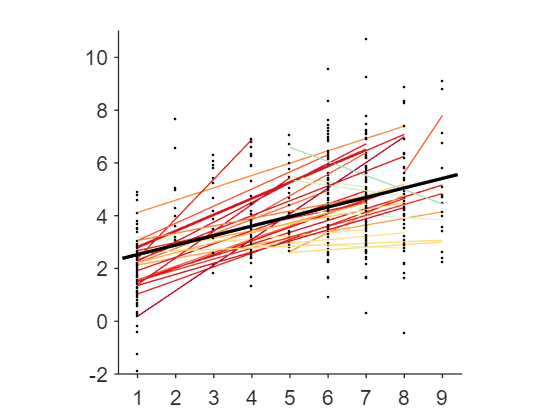

video_idx = rating(:, 1) ~= 0;
pred_rating = wb_pred_study1(video_idx, 1);
true_rating = rating(video_idx, 1);
subj_plot = subject(video_idx);
uID = unique(subj_plot);

figure
hold on
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    plot(true_rating(subj_idx), pred_rating(subj_idx), '.k', 'MarkerSize', 6)
    bls = regress(pred_rating(subj_idx), [ones(sum(subj_idx), 1), true_rating(subj_idx)]);
    plot(true_rating(subj_idx), bls(1) + bls(2) .* true_rating(subj_idx), 'Color', cols(i + nsub, :), 'LineWidth', 1)
end
bls = regress(pred_rating, [ones(length(true_rating), 1), true_rating]);
xfit = [0.6; true_rating; 9.4];
plot(xfit, bls(1) + bls(2) .* xfit, 'Color', 'k', 'LineWidth', 2.5)

set(gca, 'YLim', [-2 11], 'YTick', -2:2:10, 'XLim', [0.5 9.5], 'XTick', 1:9, 'TickDir', 'out', ...
    'FontName', fontname, 'FontSize', 16, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w')
% % colormap(gca, col_with_white)
% % caxis(gca, [-1 1])
% % colorbar
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_pred_pos', '-r400')
% close all

## Figure 3: NAES predictions, positive affective experience coded as 0

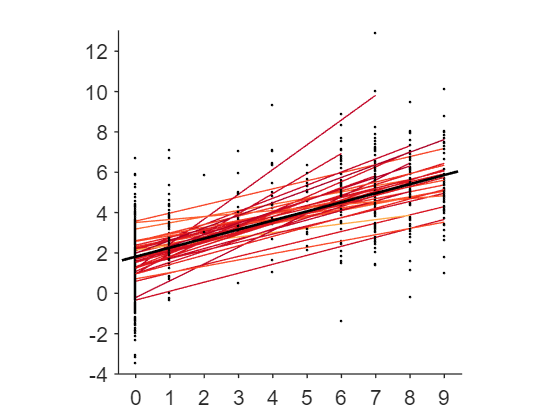

pred_rating = wb_pred_study1(:, 2);
true_rating = rating(:, 2);
subj_plot = subject;
uID = unique(subj_plot);

figure
hold on
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    plot(true_rating(subj_idx), pred_rating(subj_idx), '.k', 'MarkerSize', 6)
    bls = regress(pred_rating(subj_idx), [ones(sum(subj_idx), 1), true_rating(subj_idx)]);
    plot(true_rating(subj_idx), bls(1) + bls(2) .* true_rating(subj_idx), 'Color', cols(i + 2*nsub, :), 'LineWidth', 1)
end
bls = regress(pred_rating, [ones(length(true_rating), 1), true_rating]);
xfit = [-0.4; true_rating; 9.4];
plot(xfit, bls(1) + bls(2) .* xfit, 'Color', 'k', 'LineWidth', 2)

set(gca, 'YLim', [-4 13], 'YTick', -4:2:12, 'XLim', [-0.5 9.5], 'XTick', 0:9, 'TickDir', 'out', ...
    'FontName', fontname, 'FontSize', 16, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w')
% % colormap(gca, col_with_white)
% % caxis(gca, [-1 1])
% % colorbar
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_overall', '-r400')
% close all

## Figure 4: NAES predictions, exclude positive affective experience

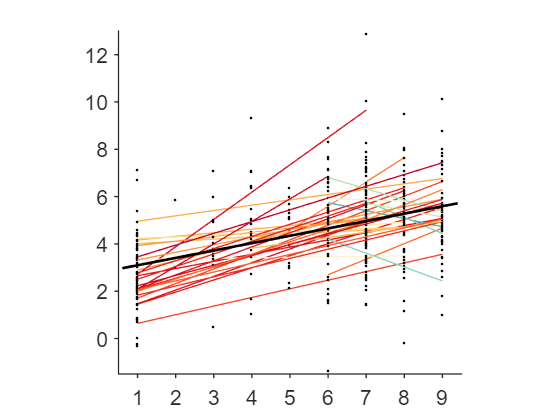

video_idx = rating(:, 2) ~= 0;
pred_rating = wb_pred_study1(video_idx, 2);
true_rating = rating(video_idx, 2);
subj_plot = subject(video_idx);
uID = unique(subj_plot);

figure
hold on
for i = 1:nsub
    subj_idx = subj_plot == uID(i);
    plot(true_rating(subj_idx), pred_rating(subj_idx), '.k', 'MarkerSize', 6)
    bls = regress(pred_rating(subj_idx), [ones(sum(subj_idx), 1), true_rating(subj_idx)]);
    plot(true_rating(subj_idx), bls(1) + bls(2) .* true_rating(subj_idx), 'Color', cols(i + 3*nsub, :), 'LineWidth', 1)
end
bls = regress(pred_rating, [ones(length(true_rating), 1), true_rating]);
xfit = [0.6; true_rating; 9.4];
plot(xfit, bls(1) + bls(2) .* xfit, 'Color', 'k', 'LineWidth', 2)

set(gca, 'YLim', [-1.5 13], 'YTick', 0:2:12, ...
    'XLim', [0.5 9.5], 'XTick', 1:9, 'TickDir', 'out', ...
    'FontName', fontname, 'FontSize', 16, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w')
% % colormap(gca, col_with_white)
% % caxis(gca, [-1 1])
% % colorbar
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_pred_neg', '-r400')
% close all